## Get Data

filename = '/home/saturn/Project-ABG/ABG_classification/data/pngs';
[testIMDS,validationIMDS,trainingIMDS] = get_rand_abgo_imds2(filename);


## Resize the data

%resize datastore to [224, 224, 3]
train_audIMDS = augmentedImageDatastore([224, 224, 3], trainingIMDS);
validation_audIMDS = augmentedImageDatastore([224, 224, 3], validationIMDS);
test_audIMDS = augmentedImageDatastore([224, 224, 3], testIMDS);

% Important datastores have been resized to fit specified for
% the model
train_audIMDS;
validation_audIMDS;
test_audIMDS;
% end of data split


mobnet_trained = load('TrainedMob2.mat');
net = mobnet_trained.net;
% analyzeNetwork(net)    % uncomment to analyze network


% layer + features
layer = 'block_11_add';
featuresTrain = activations(net,train_audIMDS,layer,'ExecutionEnvironment',"auto");
featuresTest = activations(net,test_audIMDS,layer,'ExecutionEnvironment',"auto");
whos featuresTrain

  Name                Size                        Bytes  Class     Attributes

  featuresTrain      14x14x96x7041            529933824  single              




featuresTrain = squeeze(mean(featuresTrain,[1 2]))';
featuresTest = squeeze(mean(featuresTest,[1 2]))';
whos featuresTrain

  Name                  Size              Bytes  Class     Attributes

  featuresTrain      7041x96            2703744  single              



### SVM templates 

% t_1 = templateSVM( ...
%      'Standardize','on', ...
%      'KernelFunction','gaussian' ...
%      );

t1 = templateSVM('BoxConstraint',0.7, ...
   'KernelFunction','rbf', ...
   'DeltaGradientTolerance',1e-2, ...
   'Solver','SMO', ...
   'Standardize',false);

t2 = templateSVM('BoxConstraint',0.475, ...
 'KernelFunction','polynomial', ...
 'DeltaGradientTolerance',1e-3, ...
 'PolynomialOrder',1, ...
 'Solver','ISDA', ...
 'Standardize',true);

t3 = templateSVM('BoxConstraint',0.015, ...
   'KernelFunction','linear', ...
   'DeltaGradientTolerance',1e-2, ...
   'Solver','ISDA', ...
   'Standardize',true);

t4 = templateSVM('BoxConstraint',1, ...
   'KernelFunction','gaussian', ...
   'DeltaGradientTolerance',1e-2, ...
   'Solver','SMO', ...
   'Standardize',false...
   );

template = {t1,t2,t3,t4};

### Classify, Predict, Confusion Matrices and F-Scores

accuracy = 0.5050

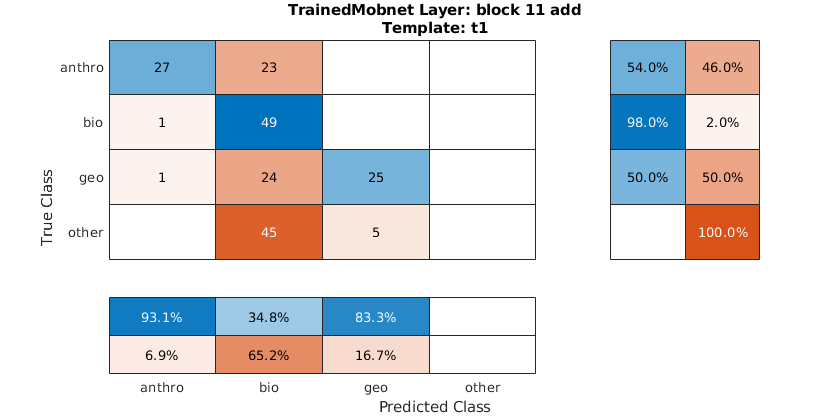

accuracy = 0.5050

fScore =     0.6835    0.5131    0.6250       NaN


avg_f_score = NaN

accuracy = 0.7250

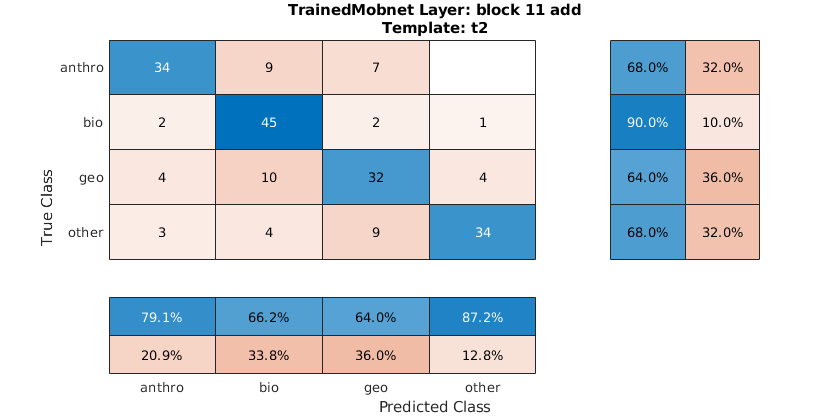

accuracy = 0.7250

fScore =     0.7312    0.7627    0.6400    0.7640


avg_f_score = 0.7245

accuracy = 0.7350

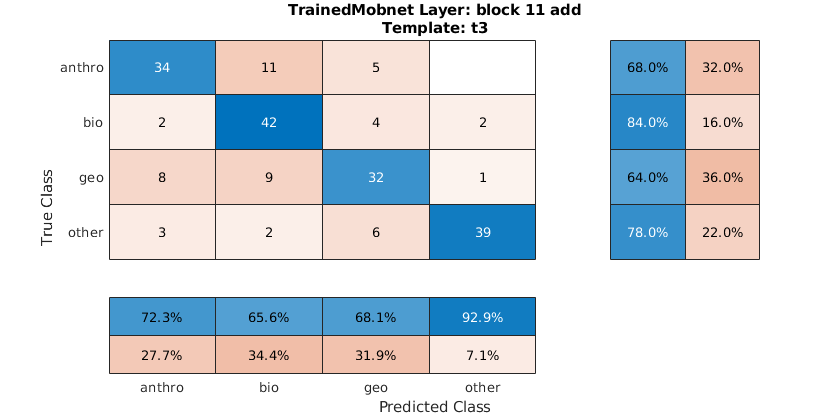

accuracy = 0.7350

fScore =     0.7010    0.7368    0.6598    0.8478


avg_f_score = 0.7364

accuracy = 0.5450

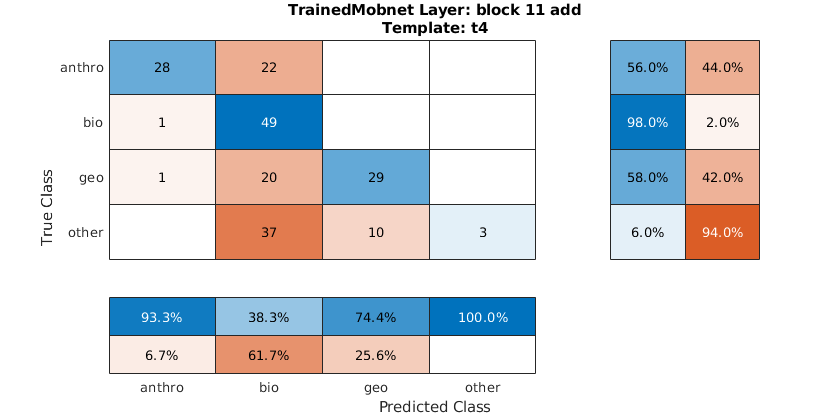

accuracy = 0.5450

fScore =     0.7000    0.5506    0.6517    0.1132


avg_f_score = 0.5039

for i=1:size(template,2)
    classifier = fitcecoc( ...
        featuresTrain, ...
        trainingIMDS.Labels, ...
        'Learners',template(i), ...
        'Options',statset('UseParallel',true) ...
        );
    
    
    YPred = predict(classifier,featuresTest);
    accuracy = mean(YPred == testIMDS.Labels)
    
    % Displaying confusion chart
    fig = figure;
    fig_Position = fig.Position;
    fig_Position(3) = fig_Position(3)*1.5;
    fig.Position = fig_Position;
    cm = confusionchart(testIMDS.Labels,YPred,'RowSummary','row-normalized','ColumnSummary','column-normalized');
    title(cm,{"TrainedMobnet Layer: block 11 add","Template: t"+i})
    
    % Calculating fScore and avg_f_score
    cm1 = cm.NormalizedValues;
    
    for i = 1:size(cm1,1)
        precision(i) = cm1(i,i)/sum(cm1(i,:));
    end
    
    for i = 1:size(cm1,1)
        recall(i) = cm1(i,i)/sum(cm1(:,i));
    end
    
    for i = 1:size(precision,2)
        fScore(i) = (2 * (precision(i) * recall(i)) / (precision(i) + recall(i)));
    end
    
    % Displaying results
    accuracy
    fScore
    avg_f_score = sum(fScore)/numel(fScore)
end